# Simulation Dynamics

This section presents the simulation dynamics of the model.

We begin by computing the baseline transition path of the economy under Business-As-Usual assumptions.

We then introduce an alternative carbon-policy scenario and solve for the corresponding transition to a net-zero economy.

Finally, we compare the two deterministic trajectories to assess the macroeconomic and climate implications of stronger mitigation efforts.

## I. Initialization of the path of the model

We start by loading the model using Dynare:

dynare model_file

Starting Dynare (version 6.1).
Calling Dynare with arguments: none
Starting preprocessing of the model file ... 
Substitution of exo lags: added 1 auxiliary variables and equations. 
Found 62 equation(s). 
Evaluating expressions... 
Computing static model derivatives (order 1). 
Normalizing the static model... 
Normalization failed with cutoff, trying symbolic normalization... 
Finding the optimal block decomposition of the stati

STEADY-STATE RESULTS:

Z                		 22.9448
L                		 10.48
gZ               		 0
gL               		 0
SIG              		 0
gSIG             		 0
THETA1           		 0
delthet          		 0
dy               		 0
de               		 0
pi               		 0.0025
r                		 0.00223451
y                		 0.978583
x                		 0.9875
M                		 1889.6
mc               		 0.75
y_n              		 0.978583
x_n              		 0.9875
rr_n             		 -0.000264827
pi_bar           		 0.0025
D                		 0.893446
s_r              		 1
s_p              		 1
s_b              		 1
s_e              		 1
mu               		 0.0001
c                		 0.966351
lb               		 1.06575
rotemberg_to_gdp 		 1.25
abatement_to_gdp 		 0
tau_USD          		 0
h                		 1.03833
d                		 0.953151
tau              		 3.98107e-07
E                		 0
rr_real          		 -0.000264827
pi100            		 0.25
rr100            		 0.2234


% solve the path for business as usual
[y_guess,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
[y_bau] 				= EP_deterministic_path(y_guess,exo_init_ts,oo_,M_,options_);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 78.5548,	 time = 0.29
Iter: 2,	 err. = 79.7931,	 time = 0.178
Iter: 3,	 err. = 0.0195392,	 time = 0.16
Iter: 4,	 err. = 7.29728e-06,	 time = 0.144

Total time of simulation: 1.086.
--------------------------------------------------------



The model has been previously estimated, so we begin by reloading the estimated parameters and the corresponding filtered shocks. The function `reload_estimated_parameters` injects the estimated parameter vector into the Dynare model structure. Once the parameter set is updated, we recompute the steady state to ensure internal consistency before running any transition or stochastic simulations.

% Reload estimation results
load('run_estimation_filtered_data.mat')
M_ = reload_estimated_parameters(M_, thetamh, theta_names);

% Recompute steady state with updated parameters
steady;

STEADY-STATE RESULTS:

Z                		 21.8293
L                		 10.48
gZ               		 0
gL               		 0
SIG              		 0
gSIG             		 0
THETA1           		 0
delthet          		 0
dy               		 0
de               		 0
pi               		 0.0025
r                		 0.00195406
y                		 0.970927
x                		 0.9875
M                		 1945.46
mc               		 0.75
y_n              		 0.970927
x_n              		 0.9875
rr_n             		 -0.000544576
pi_bar           		 0.0025
D                		 0.884691
s_r              		 1
s_p              		 1
s_b              		 1
s_e              		 1
mu               		 0.0001
c                		 0.958791
lb               		 1.06648
rotemberg_to_gdp 		 1.25
abatement_to_gdp 		 0
tau_USD          		 0
h                		 1.02968
d                		 0.951253
tau              		 3.98107e-07
E                		 0
rr_real          		 -0.000544576
pi100            		 0.25
rr100            		 0.195

## II. Checking the insample simulated path

We now validate the estimated model by comparing observed data to the smoothed transition path implied by the filtered shocks. We split the sample into an in-sample period (1985Q1–2023Q3) and an out-of-sample projection (2023Q4 onward). Using the filtered exogenous shock series, we compute the deterministic and stochastic paths of the model over these two segments. The resulting simulated series can then be plotted against the observed data to assess the model's fit and the behavior of smoothed states.


outsample_dates = dates('2023Q4'):filtered_shock_ts.dates(end);
insample_dates 	= dates('1985Q1'):dates('2023Q3');

%% CHECK SMOOTHED ESTIMATES
%% Filtered sequence
% set-up the guess for given exo_filtered_ts
[deterministic_simuls,oo_,M_]		= EP_paths_init(oo_,M_,options_,exo_init_ts);
% Step 1: Compute the deterministic path
[deterministic_simuls] 				= EP_deterministic_path(deterministic_simuls,exo_init_ts,oo_,M_,options_);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 73.0521,	 time = 0.126
Iter: 2,	 err. = 74.8406,	 time = 0.117
Iter: 3,	 err. = 0.0111518,	 time = 0.122
Iter: 4,	 err. = 9.48111e-07,	 time = 0.119

Total time of simulation: 0.757.
--------------------------------------------------------



% Step 2: Compute the stochastic path
[stochastic_simuls]   				= EP_stochastic_path(deterministic_simuls,filtered_shock_ts,oo_,M_,options_,insample_dates);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.0405759,	 time = 0.004
Iter: 2,	 err. = 0.118215,	 time = 0.004
Iter: 3,	 err. = 0.000181715,	 time = 0.004
Iter: 4,	 err. = 4.22586e-10,	 time = 0.004

Total time of simulation: 0.024.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.590724,	 time = 0.004
Iter: 2,	 err. = 0.0039654,	 time = 0.005
Iter: 3,	 err. = 2.46913e-07,	 time = 0.004

Total time of simulation: 0.018.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 0.275765,	 time = 0.004
Iter: 2,	 err. = 0.00248143,	 time = 0.004
Iter: 3,	 err. = 4.77914e-08,	 time = 0.004

Total time of simulation: 0.018.
--------------------------------------------------------


--------------------------------------------------------
MODEL SIMU

[stochastic_simuls] 				= EP_deterministic_path(stochastic_simuls,filtered_shock_ts,oo_,M_,options_,outsample_dates);

--------------------------------------------------------
MODEL SIMULATION:

Iter: 1,	 err. = 9.60859,	 time = 0.118
Iter: 2,	 err. = 0.0150361,	 time = 0.113
Iter: 3,	 err. = 2.08337e-06,	 time = 0.113

Total time of simulation: 0.527.
--------------------------------------------------------



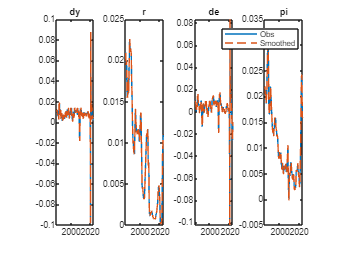


T = dseries_to_num(dataset_);
figure;
for ix=1:dataset_.size(2)
	subplot(1,dataset_.size(2),ix)
	yn = eval(['stochastic_simuls(dataset_.dates).' dataset_.name{ix} '.data']);
	plot(T,dataset_.data(:,ix),T,yn,'--')
	title(dataset_.name{ix})
end
legend('Observed','Smoothed')

## `III. `Out-of-sample news shocks on the carbon tax

We now study how out-of-sample projections react to different news about the future realization of the carbon tax. Starting from the smoothed state at the end of the sample, we construct two deterministic paths over the out-of-sample horizon:

- a **full realization** scenario, where the carbon policy parameter `varphi` is set to 1, implying that the announced carbon tax is fully implemented,

- a **no realization** scenario, where `varphi` is set to 0, meaning that the previously expected carbon tax does not materialize.

In each case, `update_terminal_state` adjusts the long run conditions of the model consistently with the news, and `EP_deterministic_path` computes the corresponding deterministic transition over `outsample_dates`.


% Introduce News shock on realization of carbon tax: Full realization
[endo_nz0,oo_nz0,M_nz0] = update_terminal_state('varphi',1,oo_,M_,filtered_shock_ts,stochastic_simuls);
[det_nz0] 				= EP_deterministic_path(endo_nz0,filtered_shock_ts,oo_nz0,M_nz0,options_,outsample_dates);

% Introduce News shock on realization of carbon tax: No realization
[endo_bau,oo_bau,M_bau] = update_terminal_state('varphi',0,oo_,M_,filtered_shock_ts,stochastic_simuls);
[det_bau] 				= EP_deterministic_path(endo_bau,filtered_shock_ts,oo_bau,M_bau,options_,outsample_dates);



We now compare three out-of-sample projection paths for key macroeconomic and climate variables:

- the **estimated tax path**, obtained from the smoothed transition using filtered shocks,

- the **Paris-Agreement realization**, where the expected future carbon tax is fully implemented (varphi = 1),

- the **laissez-faire realization**, where the expected carbon tax does not materialize (varphi = 0).

These projections show how output, inflation, interest rates, emissions, and related variables evolve from 2022 to 2100 under alternative policy-realization scenarios.

% PLOT FIGURE 3
nx = 3;ny = 3;varnames=char('lny','pi100','rr100','lny_n','output_gap','rrn100','tau_USD','E');
nn=size(varnames,1);
figure('Name','Figure 2: Model-implied projections based on alternative control rates of emissions');
for i1 =1:nn
	subplot(nx,ny,i1)
	idx = strmatch(deblank(varnames(i1,:)),M_.endo_names,'exact');
	hold on;
	plot(dseries_to_num(stochastic_simuls),stochastic_simuls.data(:,idx),'Color',[3, 161, 252]/255),'LineWidth',1.5,'MarkerIndice',1:50:size(stochastic_simuls,1))
	plot(dseries_to_num(endo_nz0),det_nz0.data(:,idx),'^-','Color',[42, 173, 81]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(stochastic_simuls,1))
	plot(dseries_to_num(endo_bau),det_bau.data(:,idx),'-s','Color',[204, 12, 38]/255,'LineWidth',1.5,'MarkerIndice',1:50:size(stochastic_simuls,1))
	hold off;
	grid on
	title(['$' M_.endo_names_tex{idx} '$ ' M_.endo_names_long{idx}],'Interpreter','latex')
	xlim([2022 2100])
end
legend('Estimated tax path','Paris-Agreement','Laissez-faire')